# İHA Uçuş Yolunu 2-B ve 3-B Haritalar Üzerinde Görselleştirme

Taksim Meydanı'ndan Çamlıca Kulesi'ne kadar simüle edilmiş bir insansız hava aracı (İHA) uçuşunu görselleştirmektedir. Öncelikle, rotayı coğrafi eksenler ve coğrafi küre üzerinde görüntüleyin. Ardından, görünümü senkronize edin ve uçuş yolunu kamera navigasyon fonksiyonlarını kullanarak görselleştirin. Son olarak, Çamlıca Kulesi'nin tepesini bir panorama olarak görüntüleyin.

## İlgili Bölgeyi 2-B'de Görselleştirme 

Konum bilgilerine göre sınırlarımız çevresindeki alanları, bölgenin hava koşulları hakkında bilgi toplama, bölgenin topografisini görüntelemek ve bölgedeki trafik veya yasadışı göç geçişlerini de tespit edip, takip etmek için İHA'ların kullanımı ayrıca  askeri görevlerimiz için önemli bir araştırma alanı haline gelmektedir. İHA, askeri amaçlar için tehlikeli olan bölgelerde seyahat edebilir. İHA'yı bir göreve göndermeden önce uçuş yolunu simüle etmek, topolojiyi ve araziyi anlamaya yardımcı olabilir. Bölgenin genel bir görünümünü ve 2-B perspektifini kazanmak için, Taksim Meydanı ve Çamlıca Kulesi'nin konumlarını coğrafi eksenler üzerinde görüntüleyin.

### Taksim Meydanı'nın Koordinatlarını Alın 

Taksim Meydanı'nın koordinatlarını belirtin. Taksim Meydanı'nın yüksekliği, deniz seviyesinden (MSL) metre cinsindendir.

% Taksim Meydanı koordinatları (lat, lon, MSL)
taksimLat = 41.0369;
taksimLon = 28.9868;
taksimH = 78; % yükseklik (tahmini)

### Çamlıca Kulesi'nin Koordinatlarını Alın

Çamlıca Kulesi'nin tepe noktasının koordinatlarını belirtin. Çamlıca Kulesi'nin yüksekliği ortometrik olup metre cinsindendir.

% Çamlıca Kulesi koordinatları (lat, lon, MSL)
camlicaLat = 41.0522;
camlicaLon = 29.0762;
camlicaH = 219; % yükseklik (tahmini)

### Taksim Meydanı ve Çamlıca Kulesi'ni 2-B'de Görüntüleme 

Bölgenin 2-B perspektifini elde etmek için, `geoaxes` ve `geoplot` fonksiyonlarını kullanarak Taksim Meydanı'nın ve Çamlıca Kulesi'nin tepe noktasını konumlarını çizin.

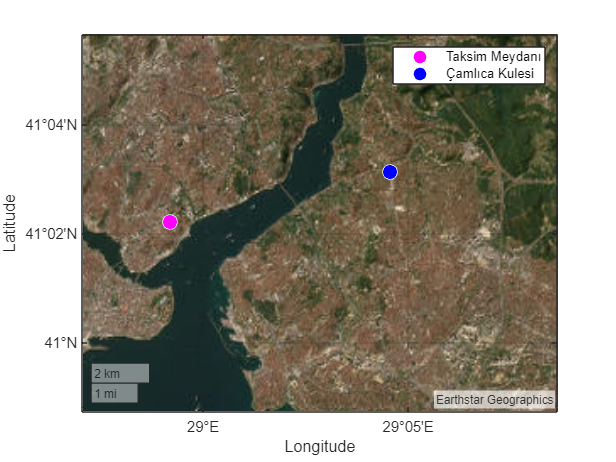

figure
geoaxes(Basemap = "satellite",ZoomLevel = 12)
hold on
geoplot(taksimLat, taksimLon, "ow", MarkerSize = 10, MarkerFaceColor= "magenta", DisplayName = "Taksim Meydanı")
geoplot(camlicaLat, camlicaLon, "ow", MarkerSize = 10, MarkerFaceColor= "blue", DisplayName = "Çamlıca Kulesi")
legend

geolimits([40.979 41.094],[28.951 29.144])

%geolimits([40.997 41.094],[28.9504 29.1123])

## Taksim Meydanı'nı 2-B ve 3-B'de Senkronize Görüntüleme

Taksim Meydanı'nı 2 boyutlu görmek için coğrafi eksenleri, 3 boyutlu görmek için coğrafi küreyi kullanın.

### Aynı figürde coğrafi eksenler ve coğrafi küre oluşturun.

Aynı kullanıcı arayüzü (UI) penceresinde coğrafi eksenler ve coğrafi küre oluşturarak 2 boyutlu ve 3 boyutlu harita görüntüsü ayarlayın. 2 boyutlu haritanın daha fazlasını görmek için coğrafi eksenlerin InnerPosition değerini OuterPosition değerine ayarlayın. Her iki harita görüntüsünü de aynı temel haritayla görüntülemek için coğrafi eksenlerin temel haritasını "uydu" olarak ayarlayın.

% UI figure oluşturma ve coğrafi eksenler ile coğrafi küre ekleme
figpos = [1000 500 800 400];
uif = uifigure("Position",figpos);
ug = uigridlayout(uif, [1, 2]);
p1 = uipanel(ug);
p2 = uipanel(ug);
gx = geoaxes(p1, Basemap= "satellite");
gg = geoglobe(p2); 
gx.InnerPosition = gx.OuterPosition;
gg.Position = [0 0 1 1];

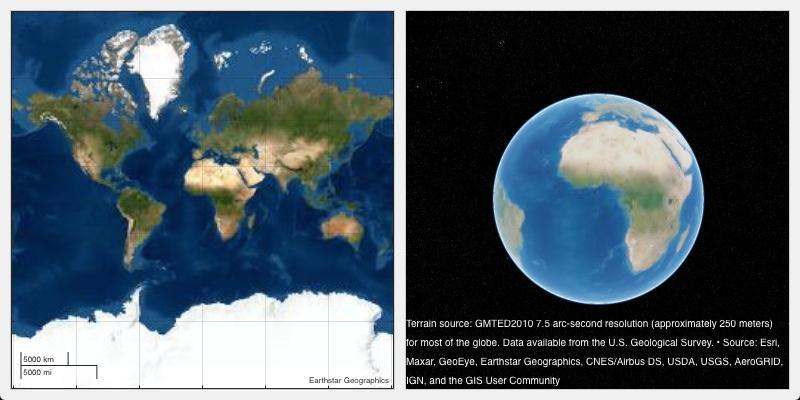

### Taksim Meydanı'nı 2-D Görüntüleyin

Taksim Meydanı'nı arazinin 200 metre üzerinden görüntüleyin. Coğrafi eksenlerin görünümünü harita merkezini ve yakınlaştırma seviyesini değiştirerek kontrol edin. Coğrafi eksenlerin görünümünü coğrafi kürenin kamera yüksekliğinden eksenler için bir yakınlaştırma seviyesine dönüştürerek coğrafi eksenlerin görünümünü coğrafi kürenin görünümüyle senkronize edebilirsiniz. Arazi yüksekliğinden yaklaşık bir yakınlaştırma seviyesi hesaplamak için heightToZoomLevel yerel işlevini kullanın.

% Coğrafi eksenler ve kürede Taksim Meydanı'nı görüntüleme
heightAboveTerrain = 200; % 200 metre yükseklik
gx.MapCenter = [taksimLat, taksimLon];
zoomLevel = heightToZoomLevel(heightAboveTerrain, taksimLat);
gx.ZoomLevel = zoomLevel;

### Taksim Meydanı'nı 3-D Görüntüleyin

Coğrafi kürenin görünümünü kameranın konumunu değiştirerek kontrol edin. Campos fonksiyonu, ortalama deniz seviyesine göre değil, WGS84 elipsoidine göre yükseklik belirtmenizi gerektirir. Taksim Meydanı'nın yüksekliğini elipsoidal yüksekliğe dönüştürün. Tüm yükseklikler metre cinsindendir.

% Coğrafi kürede konum belirleme ve kamera yüksekliği ayarlama
N = egm96geoid(taksimLat, taksimLon); % Geoid yüksekliği hesaplama
obsh = taksimH + N;
ellipsoidalHeight = obsh + heightAboveTerrain;
campos(gg, taksimLat, taksimLon, ellipsoidalHeight);
drawnow

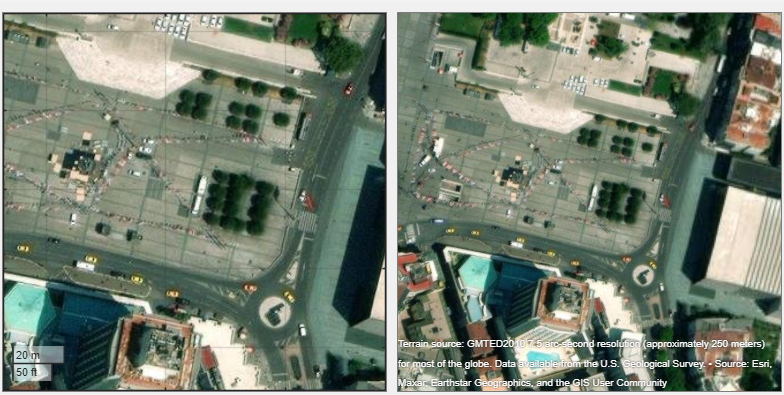

## Uçuş Rotası Verilerini İçe Aktarın ve Yön ile 3-D Mesafeyi Hesaplayın

Taksim Meydanı'nından Çamlıca Kulesi'nin zirvesine kadar olan simüle edilmiş uçuş rotasını içe aktarın. Dosya, deniz seviyesine göre referans alınmış olan İHA yolunun enlemlerini, boylamlarını ve irtifalarını içerir.

T = readgeotable("sample_uavtrack.gpx", Layer="track_points");
tlat = T.Shape.Latitude';
tlon = T.Shape.Longitude';
talt = T.Elevation';

### Uçuş Yönlerini Hesaplayın

Her izleme noktasında İHA'nın yönünü azimut fonksiyonunu kullanarak hesaplayın.

wgs84 = wgs84Ellipsoid;
theading = azimuth(tlat(1:end-1),tlon(1:end-1),tlat(2:end),tlon(2:end),wgs84);
theading = [theading(1);theading(:)];

### 3-D Mesafeleri Hesaplayın

İHA uçuş rotası için kümülatif mesafeyi hesaplayın. Mesafe fonksiyonu yükseklik veya irtifa değişikliklerini dikkate almaz. İHA'nın 3 boyutta noktadan noktaya hareket ettiği mesafeyi hesaplamak için geosantrik dik koordinatlarında (X, Y, Z) çalışmanız gerekmektedir. ecefOffset fonksiyonunu kullanarak noktadan noktaya ofset bileşenlerini (metre cinsinde) hesaplayın. İHA uçuşunun yükseklik verileri ortalama deniz seviyesine göre referans alınmıştır. ecefOffset fonksiyonunu kullanabilmek için yüksekliklerin elipsoit'e referans olması gerekir. Uçuş rotasının ortometrik yüksekliklerini elipsoid yüksekliğe (WGS84 elipsoidine göre) dönüştürün. Tüm yükseklikler metre cinsindendir.

N = egm96geoid(tlat,tlon);
h = talt + N;

Mesafe ofsetlerini hesaplayın.

lat1 = tlat(1:end-1);
lat2 = tlat(2:end);
lon1 = tlon(1:end-1);
lon2 = tlon(2:end);
h1 = h(1:end-1);
h2 = h(2:end);
[dx,dy,dz] = ecefOffset(wgs84,lat1,lon1,h1,lat2,lon2,h2);

Her bir ardışık nokta çifti arasındaki Öklid mesafesini hypot fonksiyonunu kullanarak hesaplayın. Mesafe metre cinsindendir.

distanceIncrementIn3D = hypot(hypot(dx, dy), dz);

3 boyutta kümülatif mesafeyi ve toplam mesafeyi metre cinsinden hesaplayın.

cumulativeDistanceIn3D = cumsum(distanceIncrementIn3D);
totalDistanceIn3D = sum(distanceIncrementIn3D);
fprintf("Toplam İHA izleme mesafesi %f metre.\n",totalDistanceIn3D)

Toplam İHA izleme mesafesi 7532.953887 metre.


Animasyon çizimi için kullanılacak kümülatif mesafe için bir değişken atayın.

tdist = [0 cumulativeDistanceIn3D];

## Taksim Meydanı'ndan Çamlıca Kulesi'nin Zirvesine Kadar Olan Uçuş Hattını Çizin

Simüle edilmiş uçuş hattını Taksim Meydanı'nından Çamlıca Kulesi'nin zirvesine kadar çizin. Uçuş hattını çizin. Varsayılan olarak, coğrafi küre hattı görüntü merkezine yerleştirir. Coğrafi eksenlerin görünümü değişmez çünkü daha önce MapCenter ve ZoomLevel değerlerini ayarladınız.

geoplot3(gg,tlat,tlon,talt,"c","LineWidth",2,"HeightReference","geoid")
ptrack = geoplot(gx,tlat,tlon,"c","LineWidth",2);

Harita merkezini ve yakınlaştırma seviyesini, küre için kamera yüksekliğini eksenler için yakınlaştırma seviyesine dönüştürerek 3 boyutlu görünümle tutarlı olacak şekilde ayarlayın.

[clat,clon,cheight] = campos(gg);
gx.MapCenter = [clat,clon];
gx.ZoomLevel = heightToZoomLevel(cheight, clat);
drawnow

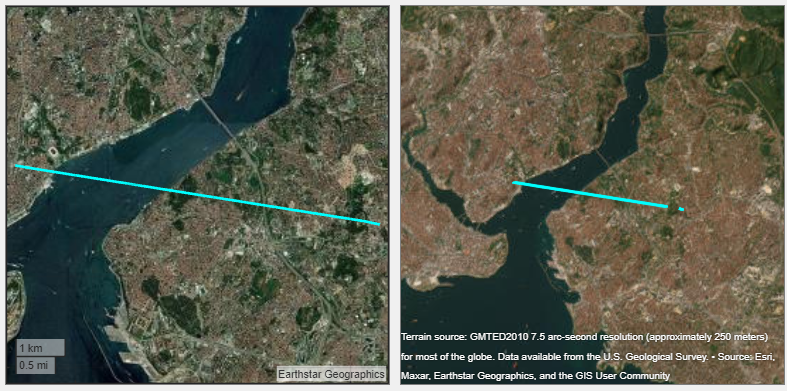

## İlk Görünümü Taksim Meydanı'nından Çamlıca Kulesi'nin Zirvesine Ayarlayın

Uçuş hattını başlangıç noktasından görüntülemek için kamera konumunu rotanın ilk koordinatına ayarlayın. Daha iyi bir perspektif için kamera yüksekliğini rotanın yüksekliğinden yaklaşık 75 metre yukarıya ayarlayın. Kameranın eğimini -90 olarak ayarlayarak gözlemevine doğru düz bakın. Rotayı görüntülemek için yönü hesaplanmış yön dizisinin üçüncü elemanına ayarlayın, çünkü rotanın ilk iki noktası aynı konumdadır ve bu konumlar için hesaplanan yön 0'dır.

campos(gg,tlat(1),tlon(1))
camheight(gg,talt(1) + 75)
campitch(gg,-90)
camheading(gg,theading(3))

İHA'nın konumunu 2 boyutlu haritada ve uçuş rotasının başlangıç ve bitiş noktalarını işaretçilerle gösterin. İHA rotası ve işaretçiler için bir açıklama oluşturun.  

hold(gx,"on")
marker = geoplot(gx,tlat(1),tlon(1),"ow","MarkerSize",10,"MarkerFaceColor","k");
mstart = geoplot(gx,tlat(1),tlon(1),"ow","MarkerSize",10,"MarkerFaceColor","magenta");
mend = geoplot(gx,tlat(end),tlon(end),"ow","MarkerSize",10,"MarkerFaceColor","blue");

marker.DisplayName = "Current Location";
mstart.DisplayName = "Start Location";
mend.DisplayName = "End Location";
ptrack.DisplayName = "UAV Track";
legend(gx)

Bölgenin topolojisini görmek için temel haritayı değiştirin.

gx.Basemap = "topographic";

İHA'nın konumunu, irtifasını ve yönünü İHA'nın konumuna karşılık gelen özel bir veri ipucu kullanarak görüntüleyin. Taksim Meydanı'nın konumundan mesafeyi dahil edin.

dt = datatip(ptrack,"DataIndex",1,"Location","southeast");
dtrow = dataTipTextRow("Distance",tdist);
dtrow(end+1) = dataTipTextRow("Altitude",talt);
dtrow(end+1) = dataTipTextRow("Heading",theading);
ptrack.DataTipTemplate.DataTipRows(end+1:end+3) = dtrow;

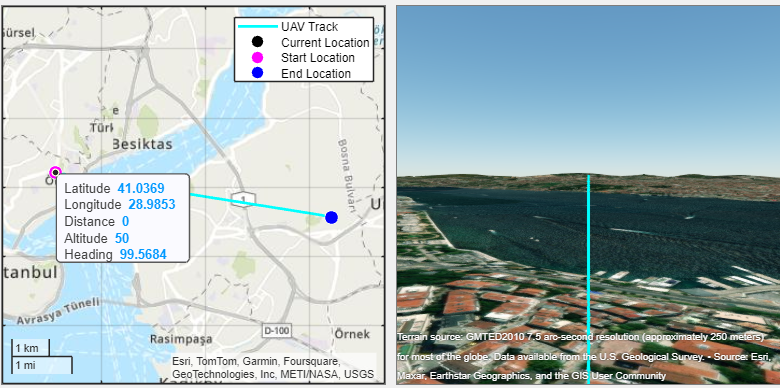

## Taksim Meydanı'nından Çamlıca Kulesi'nin Zirvesine Uçun

Taksim Meydanı'nından Çamlıca Kulesi'nin zirvesine doğru bir uçuşu animasyonlaştırın. İHA'nın konumunu 2 boyutlu haritada işaretleyerek ve veri ipucunu güncelleyerek gösterin. 3 boyutlu uçuşu kamera konumunu ayarlayarak animasyonlaştırın. İHA rotasının daha iyi görülebilmesi için kamera yüksekliğini uçuş rotasının 100 metre üzerine ayarlayın. İHA volkanın zirvesine doğru hareket ettiği sırada uçuş rotasının daha iyi görülebilmesi için kamera eğim değerini güncelleyin. Mevcut konum, irtifa ve yön bilgilerini görmek için veri ipucunu güncelleyin.

pitch = -2.7689;
campitch(gg,pitch)

for k = 2:(length(tlat)-1)    
    campos(gg,tlat(k),tlon(k))
    camheight(gg,talt(k)+100)
    camheading(gg,theading(k))
    
    set(marker,"LatitudeData",tlat(k),"LongitudeData",tlon(k));
    dt.DataIndex = k;
    
    drawnow
    pause(.25)
end

Invalid or deleted object.

Error in globe.graphics.GeographicGlobe/campos


campos(gg,tlat(end),tlon(end),talt(end)+100)
dt.DataIndex = length(tlat);

## Çamlıca Kulesi'nin Zirvesinden 360 Derecelik Bir Panorama Görünteleyin

Çamlıca Kulesi'nin zirvesinden 360 derecelik bir panorama görüntülemek için kameranın yönünü 360 derece döndürün. Saat yönünde 5 derecelik bir adımla döndürün ve bir sonraki 5 derecelik adıma başlayın. Yön veri ipucunu güncelleyin

initialHeading = camheading(gg);
increment = 5;
initialHeading = initialHeading + (increment - mod(initialHeading,increment));

filename = 'panoramic.gif';
for degree = initialHeading:increment:initialHeading+360
    heading = mod(degree,360);
    ptrack.DataTipTemplate.DataTipRows(end).Value(dt.DataIndex) = heading;
    camheading(gg,heading);
    drawnow
end

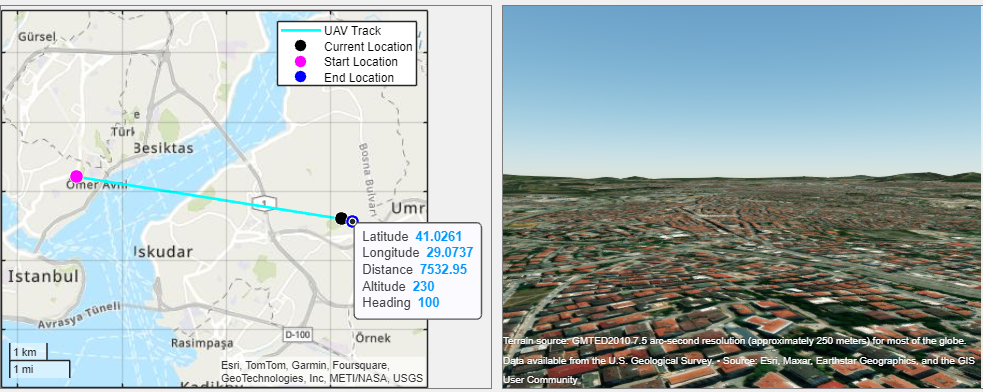

## Yerel Fonksiyonlar

### Yüksekliği (WGS84 elipsoidine göre metre cinsinden) Yakınlaştırma Seviyesine Dönüştürün

function zoomLevel = heightToZoomLevel(height, lat)
    earthCircumference = 2 * pi * 6378137;
    zoomLevel = log2((earthCircumference *cosd(lat)) / height) + 1;
    zoomLevel = max(0, zoomLevel);
    zoomLevel = min(19, zoomLevel);
end